# **READING THE DESIRED DATASTORE**

ds2_6=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\ieee-phm-2012-data-challenge-dataset luck loek\Test_set\Bearing2_6\*acc*.csv'); % this datastore only reads acceleration files acceleration files and ignores the rest temperature data files if any in the dataset

ds2_7=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\ieee-phm-2012-data-challenge-dataset luck loek\Test_set\Bearing2_7\*acc*.csv');

ds3_3=tabularTextDatastore('D:\EEE\LABS\DSP Lab Sem V\ieee-phm-2012-data-challenge-dataset luck loek\Test_set\Bearing2_7\Be\*acc*.csv');

ds1_1=tabularTextDatastore('D:\New folder\Learning_set\Bearing2_2\*acc*.csv');

x= readall(ds1_1);  % Please enter the datastore which you want to analyze
Xacc=x.Var5;         %  VAR5 horizontal acceleration of the bearing
Yacc=x.Var6;         %  VAR6 vertical acceleration of the bearing

# **DOWN SAMPLING**

-   **using 2-D **`STFT SPECTROGRAMS`*** used to justify why downsampling factor 2 is justified***

%STFT spectrogram to identify the relevant spectrogram in both the
%horizontal and vertical acceleration to determine optimal downsample factor
stft(Xacc,25600,"Window",hann(512,"periodic"),"OverlapLength",128,"FFTLength",512); % Hanning window of length 512 is applied 
colormap jet;


stft(Yacc,25600,"Window",hann(512,"periodic"),"OverlapLength",128,"FFTLength",512); 
colormap jet;

X = lowpass(Xacc,6400,25600,'Steepness',0.85,'StopbandAttenuation',60);% Applying lowpass so as to prevent folding in new down sampled signal
Y = lowpass(Yacc,6400,25600,'Steepness',0.85,'StopbandAttenuation',60);% Applying lowpass so as to prevent folding in new down sampled signal

old_sample_quantity=length(Xacc) % No. of samples before downsampling 

- **Applying DOWNSAMPLING commands**

X=downsample(X,2);
Y=downsample(Y,2);
new_sample_quantity=length(X) % No. of samples after downsampling 

new_sample_quantity = 1020160

***Here , we can see no. of samples has clearly reduced to half ***

fs=25600/2 ;% New sampling frequency
t=linspace(1/fs,length(X)/fs,length(X))

t =     0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0005    0.0006    0.0007    0.0008    0.0009    0.0009    0.0010    0.0011    0.0012    0.0013    0.0013    0.0014    0.0015    0.0016    0.0016    0.0017    0.0018    0.0019    0.0020    0.0020    0.0021    0.0022    0.0023    0.0023    0.0024    0.0025    0.0026    0.0027    0.0027    0.0028    0.0029    0.0030    0.0030    0.0031    0.0032    0.0033    0.0034    0.0034    0.0035    0.0036    0.0037    0.0037    0.0038    0.0039


- **PLOTS OF DOWNSAMPLED SIGNAL**

plot(t,X)
xlabel('time(s)');
ylabel('Horizontal acceleration(g)')
plot(t,Y)
xlabel('time(s)');
ylabel('Vertical acceleration(g)')

# **MOVING AVERAGES & SMOOTHING FUNCTIONS ON ACCELERATION AMPLITUDES**

## **MOVING AVERAGES & SMOOTHING FUNCTIONS ON HORIZONTAL ACCELERATION**

- **Simple Moving Avg(SMA)**

Horizontal_SMA=movavg(X,'simple',10); % Simple moving average %window size=10

 
plot(t,X,'.g',t,Horizontal_SMA);%Plotting w.r.t raw signal 
ylabel('Horizontal acceleration(g)');
xlabel('time(s)')
legend('Raw signal','Simple moving average window = 10')


- **Exponential Moving Avg(EMA)**

movavgExp = dsp.MovingAverage('Method','Exponential weighting','ForgettingFactor',0.7);%EMA with correction factor 0.7
Horizontal_EMA=movavgExp(X);


plot(t,X,'.g',t,Horizontal_EMA);%Plotting w.r.t raw signal 
ylabel('Horizontal acceleration(g)');
xlabel('time(s)')
legend('Raw signal','Exponential moving average α=0.7')


- **Exponential Smoothing(ES)**

movavgExp = dsp.MovingAverage('Method','Exponential weighting','ForgettingFactor',0.8553); % exponenetial Smoothing correction factor 0.8553
Horizontal_ES=movavgExp(X);


plot(t,X,'.g',t,Horizontal_ES);%Plotting w.r.t raw signal 
ylabel('Horizontal acceleration(g)');
xlabel('time(s)')
legend('Raw signal','Exponentially smoothed α=0.8553')


- **Centered Moving Avg(CMA)**

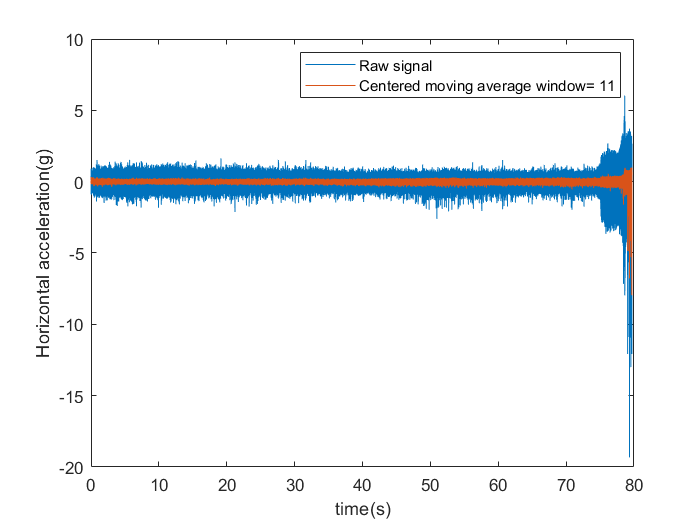

Horizontal_CMA=movmean(X,11); % Centered moving average OR Simple Smoothing


plot(t,X,'.g',t,Horizontal_CMA);%Plotting w.r.t raw signal 
ylabel('Horizontal acceleration(g)');
xlabel('time(s)')
legend('Raw signal','Centered moving average window= 11')

- **Triangular Moving Avg(TMA)**

Horizontal_TMA=movavg(X,'triangular',10); % Triangular moving average OR doubled SMA


plot(t,X,'.g',t,Horizontal_TMA);%Plotting w.r.t raw signal 
ylabel('Horizontal acceleration(g)');
xlabel('time(s)')
legend('Raw signal','Triangular moving average window = 10')


## **MOVING AVERAGES & SMOOTHING FUNCTIONS ON VERTICAL ACCELERATION**

- **Simple Moving Avg(SMA)**

Vertical_SMA=movavg(Y,'simple',10); % Simple moving average


plot(t,Y,'.g',t,Vertical_SMA);%Plotting w.r.t raw signal 
ylabel('Vertical acceleration(g)');
xlabel('time(s)')
legend('Raw signal','Simple moving average')


- **Exponential Moving Avg(EMA)**

movavgExp = dsp.MovingAverage('Method','Exponential weighting','ForgettingFactor',0.7); %EMA alpha= 0.7
Vertical_EMA=movavgExp(Y);


plot(t,Y,'.g',t,Vertical_EMA);%Plotting w.r.t raw signal 
ylabel('Vertical acceleration(g)');
xlabel('time(s)')
legend('Raw signal','Exponential moving average α=0.7')

- **Exponential Smoothing(ES)**

movavgExp = dsp.MovingAverage('Method','Exponential weighting','ForgettingFactor',0.8553); % exponenetial Smoothing
Vertical_ES=movavgExp(Y);


plot(t,Y,'.g',t,Vertical_ES);%Plotting w.r.t raw signal 
ylabel('Vertical acceleration(g)');
xlabel('time(s)')
legend('Raw signal','Exponentially smoothed α=0.8553')

- **Centered Moving Avg(CMA)**

Vertical_CMA=movmean(Y,10); % Centered moving average OR Simple Smoothing


plot(t,Y,'.g',t,Vertical_CMA);%Plotting w.r.t raw signal 
ylabel('Vertical acceleration(g)');
xlabel('time(s)')
legend('Raw signal','Centered moving Average')

- **Triangular Moving Avg(TMA)**

Vertical_TMA=movavg(Y,'triangular',10); % Triangular moving average OR doubled smoothed SMA


plot(t,Y,'.g',t,Vertical_TMA);%Plotting w.r.t raw signal 
ylabel('Vertical acceleration(g)');
xlabel('time(s)')
legend('Raw signal','Triangular moving Average')

# **Fourier smoothing using PSD on Horizontal Acceleration**

fs=12800;
n=length(X); %length of signal 
fcapH=fft(X,n); %performing fourier transform 
PSDH=fcapH.*conj(fcapH)/n;
freqH=fs/n*(0:n);%frequency vector 

- **PLOTTING PSD FOR HORIZONTAL ACCELERATION**

L=1:floor(n/2); %using half length beacause FFT transform gives a symmetric matrix and only half length is needed to plot PSD 
figure(2)
plot(freqH(L),PSDH(L),'linewidth',3)
xlabel('frequency')
ylabel('Power spectral density(dB)')

**Using PSD to filter out the Low power frequencies **

**Threshold for Bearing  1_1 - 5 dB   |  Bearing 1_2  - 2 dB  ***** |*****       Bearing 2_1 - 2 dB    |   Bearing 2_2  - 1.5 dB  |    Bearing 3_1  -  0.8 dB  |    Bearing 3_2  - 0.8 dB     |  Bearing 2_6 - 0.4 dB    | Bearing 2_7 - 0.54 dB    | Bearing 3_3  - 0.29 dB     |**

** Threshold limits were decided after obtaining the psd plots**

indices=PSDH>0.29;            %threshold for bearing 1_1 Horizontal Accleeration is 5 dB
PSDcleanH=PSDH.*indices;
fcapH=indices.*fcapH;
X_fft_filterd=ifft(fcapH);  %fourier filtered signal obtained using ifft

plot(t,X,'.g',t,X_fft_filterd);%Plotting w.r.t raw signal 
ylabel('Horizontal acceleration(g)');
xlabel('time(s)')
legend('Raw signal','Fourier smoothed')

# **Fourier smoothing using PSD on Vertical Acceleration**

n=length(Y);
fcapV=fft(Y,n);
PSDV=fcapV.*conj(fcapV)/n;
freqV=fs/n*(0:n);

- **PLOTTING PSD FOR VERTICAL ACCELERATION**


L=1:floor(n/2);
figure(3)
plot(freqV(L),PSDV(L),'linewidth',3)
xlabel('frequency')
ylabel('Power spectral density(dB)')

**Threshold for Bearing  1_1 - 1 dB   |  Bearing 1_2  - 2.5 dB   |       Bearing 2_1 - 0.5 dB    |   Bearing 2_2  - 0.15 dB  |    Bearing 3_1  -  0.6 dB  |    Bearing 3_2  - 0.2 dB    |       Bearing 2_6 - 0.35 dB  |       Bearing 2_7 - 0.30 dB  |    Bearing 3_3  -  0.22 dB **

** threshold limits were decided after obtaining the psd plots **

indices=PSDV>0.22;        %threshold for bearing 1_1 Vertical Accleeration is 1 dB
PSDcleanV=PSDV.*indices;
fcapV=indices.*fcapV;
Y_fft_filterd=ifft(fcapV); %fourier filtered signal obtained using ifft

plot(t,Y,'.g',t,Y_fft_filterd);%Plotting w.r.t raw signal 
ylabel('Vertical acceleration(g)');
xlabel('time(s)')
legend('Raw signal','Fourier smoothed')

# **HAMPEL FILTER**

**Applying Hampel Filter on already fourier filtered signals to remove outliers**

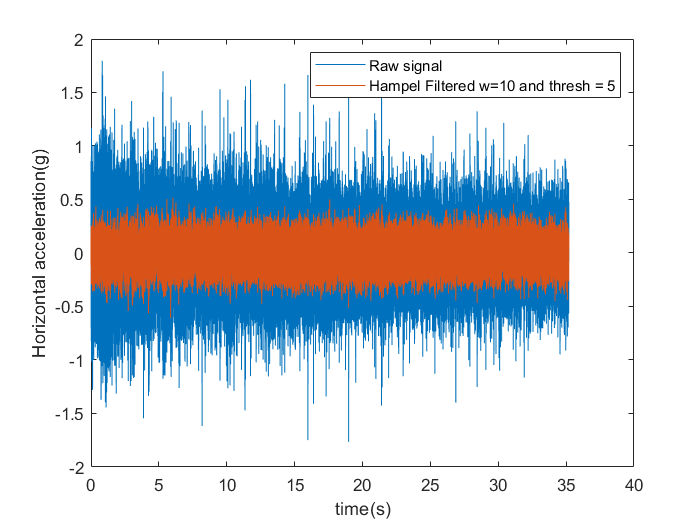

X_final=hampel(X_fft_filterd,10,5); %Horizontal Acceleration % 10 = half window width this gives 10 samples on either side so total window size = (10*2 + 1).Sample in the middle is the median


plot(t,X,'.g',t,X_final,'b');%Plotting w.r.t raw signal 
ylabel('Horizontal acceleration(g)');
xlabel('time(s)')
legend('Raw signal','Hampel Filtered w=10 and thresh = 5')

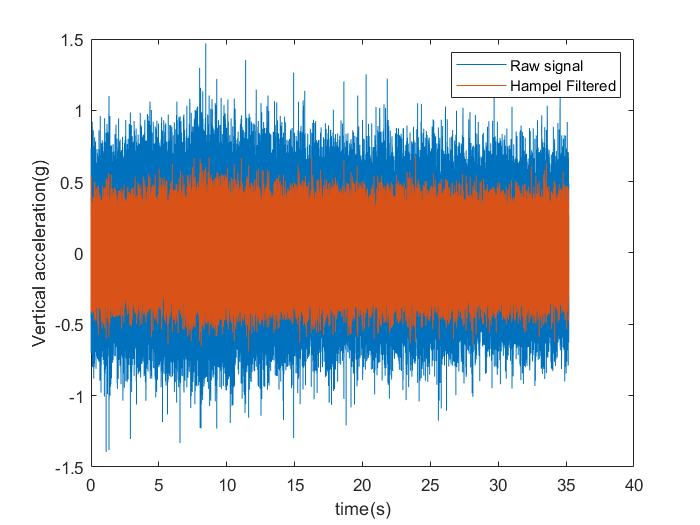


Y_final=hampel(Y_fft_filterd,10); %Vertical Acceleration
plot(t,Y,'.g',t,Y_final);%Plotting w.r.t raw signal 
ylabel('Vertical acceleration(g)');
xlabel('time(s)')
legend('Raw signal','Hampel Filtered ')

# **EMD- EMPERICAL MODE DECOMPOSITION **

[X_EMD,X_Residual]=emd(X,"MaxNumIMF",3); % Generating 3 IMFs of Raw Signal
X_IMF2=X_EMD(:,2);                       % Extracting 2nd intrinsic mode function since it gives best results 
plot(t,X,'.g',t,X_IMF2);                 % Plotting w.r.t raw signal 
ylabel('Horizontal acceleration(g)');
xlabel('time(s)')
legend('Raw signal','signal After EMD')

[Y_EMD,Y_Residual]=emd(Y,"MaxNumIMF",3); % Generating 3 IMFs of Raw Signal
Y_IMF2=Y_EMD(:,2)                        % Extracting 2nd intrinsic mode function since it gives best results 
plot(t,Y,'.g',t,Y_IMF2);                 % Plotting w.r.t raw signal 
ylabel('Vertical acceleration(g)');
xlabel('time(s)')
legend('Raw signal','signal After EMD')
